%{
clear();


load("test_signal\sin1d0.mat");
Inp_sine = data{1}.Values.Data

Inp_sine =          0
    0.0754
    0.1508
    0.2262
    0.3016
    0.3769
    0.4523
    0.5276
    0.6029
    0.6782


Measure_sine = data{2}.Values.Data

Measure_sine = 10001×1 single column vector
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



TimeArr = data{1}.Values.Time

TimeArr =          0
    0.0010
    0.0020
    0.0030
    0.0040
    0.0050
    0.0060
    0.0070
    0.0080
    0.0090



load("test_signal\ramp2d4.mat");
Inp_ramp = data{1}.Values.Data

Inp_ramp =          0
    0.0024
    0.0048
    0.0072
    0.0096
    0.0120
    0.0144
    0.0168
    0.0192
    0.0216


Measure_ramp = data{2}.Values.Data

Measure_ramp = 10001×1 single column vector
  221.6602
  213.9903
  209.3884
  214.7573
  214.7573
  207.8544
  200.9515
  203.2525
  205.5534
  205.5534



load("test_signal\pulse1d0.mat");
Inp_step = data{1}.Values.Data

Inp_step =     12
    12
    12
    12
    12
    12
    12
    12
    12
    12


Measure_step = data{2}.Values.Data

Measure_step = 10001×1 single column vector
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



load("test_signal\stair1.mat");
Inp_stair = data{1}.Values.Data

Inp_stair =      6
     6
     6
     6
     6
     6
     6
     6
     6
     6


Measure_stair = data{2}.Values.Data

Measure_stair = 10001×1 single column vector
  216.2913
  213.9903
  210.9224
  208.6214
  207.8544
  204.7864
  200.1845
  202.4855
  210.1554
  214.7573



load("test_signal\chirp2.mat");
Inp_chirp = 12 * data{1}.Values.Data

Inp_chirp =          0
    0.0754
    0.1509
    0.2263
    0.3018
    0.3773
    0.4528
    0.5284
    0.6039
    0.6794


Measure_chirp = data{2}.Values.Data

Measure_chirp = 10001×1 single column vector
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0



Measure_test_signals = [
    Measure_sine;
    Measure_ramp;
    Measure_step;
    Measure_stair;
    Measure_chirp
];

save("test_signal\Test_Dataframe.mat")
%}

load("test_signal\Test_Dataframe.mat");

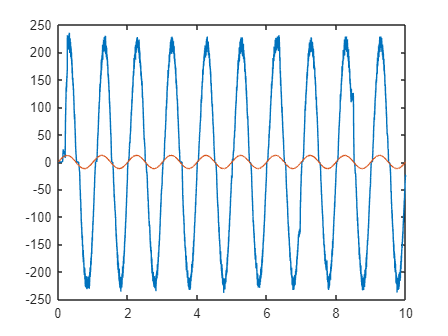

% Plot
figure(Name='Validation Testing Signal')
plot(TimeArr,Measure_sine,TimeArr,Inp_sine)

Test_signal_names = {'Sine', 'Ramp', 'Step', 'Stair', 'Chirp'};

% Store signals in arrays for easy iteration
Inp_test_signals = {Inp_sine, Inp_ramp, Inp_step, Inp_stair, Inp_chirp};
Measure_test_signals = {Measure_sine, Measure_ramp, Measure_step, Measure_stair, Measure_chirp};


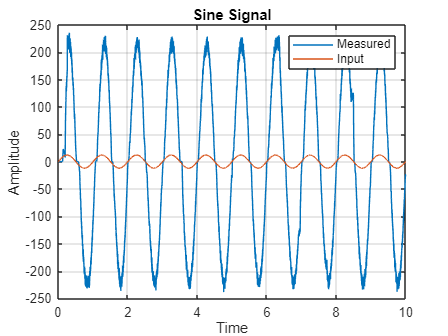

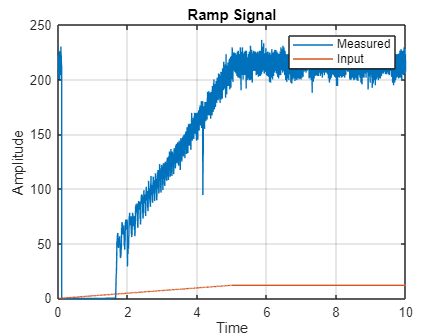

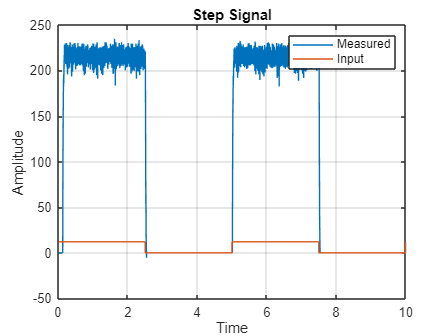

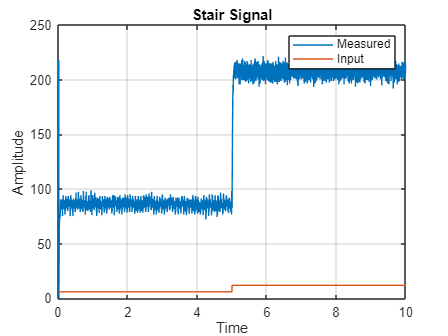

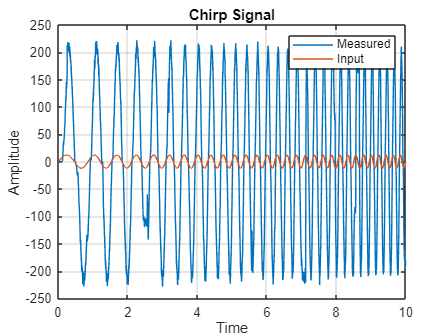


% Loop through each test signal and plot in a separate figure
for i = 1:length(Test_signal_names)
    figure('Name', [Test_signal_names{i}, ' Signal']);
    plot(TimeArr, Measure_test_signals{i}, TimeArr, Inp_test_signals{i});
    title([Test_signal_names{i}, ' Signal']);
    legend('Measured', 'Input');
    xlabel('Time');
    ylabel('Amplitude');
    grid on;
end

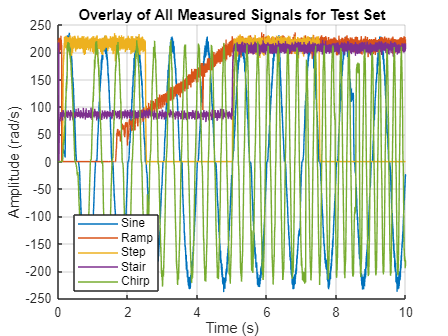


% Final "Conclusion" graph (all measured signals in one plot)
figure('Name', 'Conclusion: Overlay of All Measured Signals');
hold on;
for i = 1:length(Test_signal_names)
    plot(TimeArr, Measure_test_signals{i});
end
hold off;
title('Overlay of All Measured Signals for Test Set');
legend(Test_signal_names, 'Location', 'best');
xlabel('Time (s)');
ylabel('Amplitude (rad/s)');
grid on;

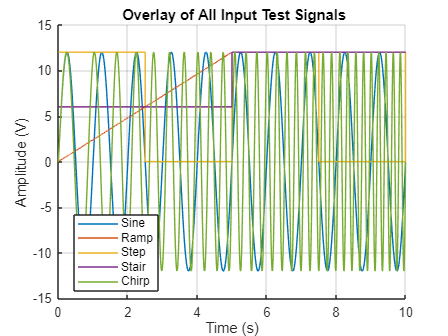


% Final "Conclusion" graph (all measured signals in one plot)
figure('Name', 'Conclusion: Overlay of All Input Test Signals');
hold on;
for i = 1:length(Test_signal_names)
    plot(TimeArr, Inp_test_signals{i});
end
hold off;
title(' Overlay of All Input Test Signals');
legend(Test_signal_names, 'Location', 'best');
xlabel('Time (s)');
ylabel('Amplitude (V)');
grid on;

load("model_predict\predict_sin01.mat");

Error using load
Unable to find file or directory 'model_predict\predict_sin01.mat'.

%model_predict_signals = data.Data
model_predict_signals = {data.Data(:, 1), 
                        data.Data(:, 2),
                        data.Data(:, 3),
                        data.Data(:, 4),
                        data.Data(:, 5)}

## Plot input test, measure, predict and Compare


% Define colors for better visibility
colors = {'b', 'r', 'g'}; % Blue for input, Red for measured, Green for model prediction

% Loop through each test signal and plot with model predictions
for i = 1:length(Test_signal_names)
    figure('Name', [Test_signal_names{i}, ' Comparison']);
    
    % Plot Input Test Signal
    plot(TimeArr, Inp_test_signals{i}, 'Color', colors{1}, 'LineWidth', 1.5);
    hold on;
    
    % Plot Measured Signal
    plot(TimeArr, Measure_test_signals{i}, 'Color', colors{2}, 'LineWidth', 1.5);
    
    % Plot Model Predicted Signal
    plot(TimeArr, model_predict_signals{i}, 'Color', colors{3}, 'LineWidth', 1.5);
    
    % Add Title and Legend
    title([Test_signal_names{i}, ' - Input vs Measured vs Predicted']);
    legend('Input Signal', 'Measured Signal', 'Predicted Signal', 'Location', 'best');
    xlabel('Time');
    ylabel('Amplitude');
    grid on;
    hold off;
end

% Function to compute R-squared
function R_squared = compute_rsquare(y_actual, y_pred)
    % Ensure input vectors are column vectors
    y_actual = y_actual(:);
    y_pred = y_pred(:);
    
    % Compute SSE (Sum of Squared Errors)
    SSE = sum((y_actual - y_pred).^2);
    
    % Compute SStot (Total Sum of Squares)
    SS_tot = sum((y_actual - mean(y_actual)).^2);
    
    % Compute R-squared
    R_squared = 1 - (SSE / SS_tot);
end

compute_rsquare(Measure_test_signals{1}, model_predict_signals{1})

% Compute R-squared for each signal type
R_squared_values = zeros(1, length(Test_signal_names));

fprintf('R-squared values for each test signal:\n');
for i = 1:length(Test_signal_names)
    R_squared_values(i) = compute_rsquare(Measure_test_signals{i}, model_predict_signals{i});
    fprintf('%s: %.4f\n', Test_signal_names{i}, R_squared_values(i));
end